## Figure 2.f.

                        %organoid, channel, month 
o1_ch8_m1 = channel("rawData.csv", 1, 8, 1);
o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

                        %thres, pre_time, post_time
o1_ch8_m1.detectSpikes(5,2,2);

o1_ch8_m1.getPCScores();
                           %clusternum, seednum
o1_ch8_m1.getKmeansClusters(3,1);

o1_ch8_m1.getThetas();

ch =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 8
                    month: 1
                       sf: 3.0518e+03
                  msPerTs: 0.3277
              nTimestamps: 61183
                startTime: 30.0312
                        t: [61183×1 double]
                      raw: [61183×1 double]
                 filtered: [61183×1 double]
        timestampsPrePeak: 7
       timestampsPostPeak: 7
          spikeTimestamps: [1×171 double]
    spikeTimestampsMatrix: [3×168 double]
           spikeWaveforms: [171×15 double]
                 PCScores: [171×2 double]
                 clusters: [171×1 double]
                nClusters: 3
        nSpikesPerCluster: [3×1 double]
                      ISI: []
               thetaWaves: [61183×1 double]
              thetaPhases: [61183×1 double]
         spikeThetaAngles: [171×1 double]
            clusterColors: [6×1 string]


raw trace, filtered trace, raster polot

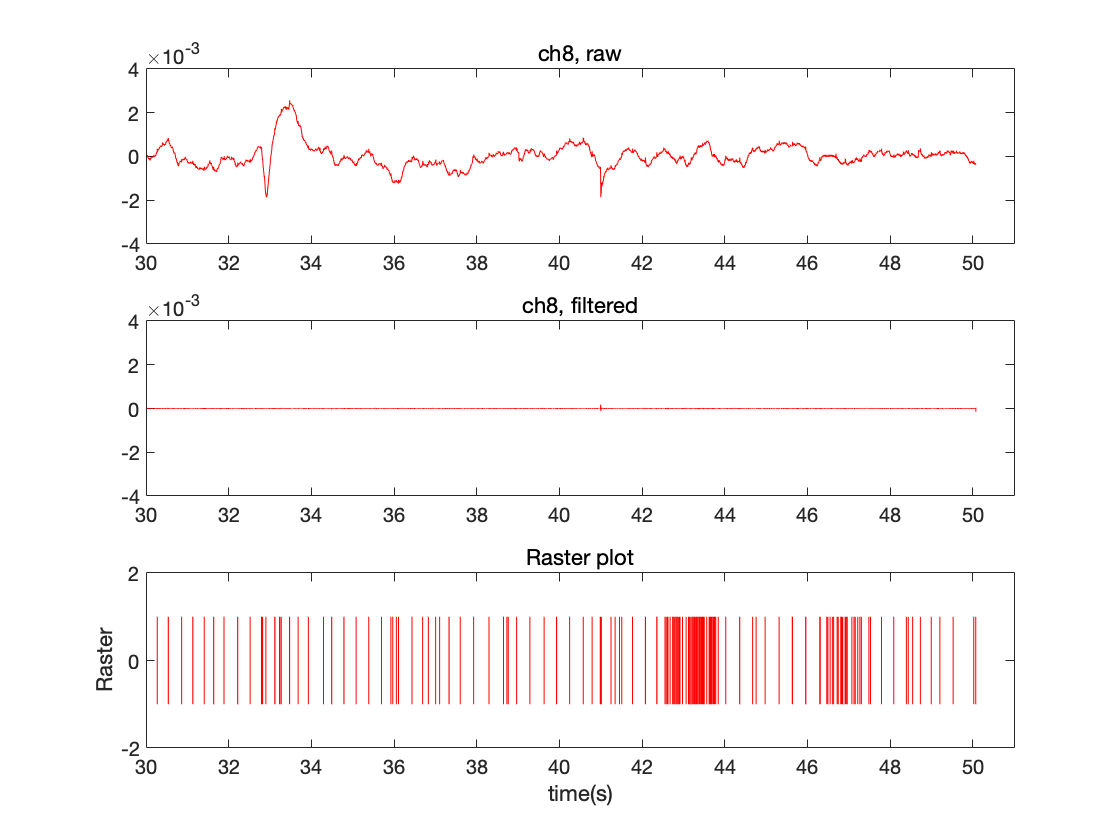

figure
subplot(3,1,1)
pRaw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
pRaw.Color = 'red';
title('ch8, raw');
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

subplot(3,1,2)
pFiltered = plot(o1_ch8_m1.t, o1_ch8_m1.filtered);
pFiltered.Color = 'red';
title('ch8, filtered');
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

subplot(3,1,3)
o1_ch8_m1.drawRaster('red');
xlim([30,51]); %xlim 조절 가능

## Figure 2.g.

zoom-in window on the same spike(20th, for example) before and after filtering

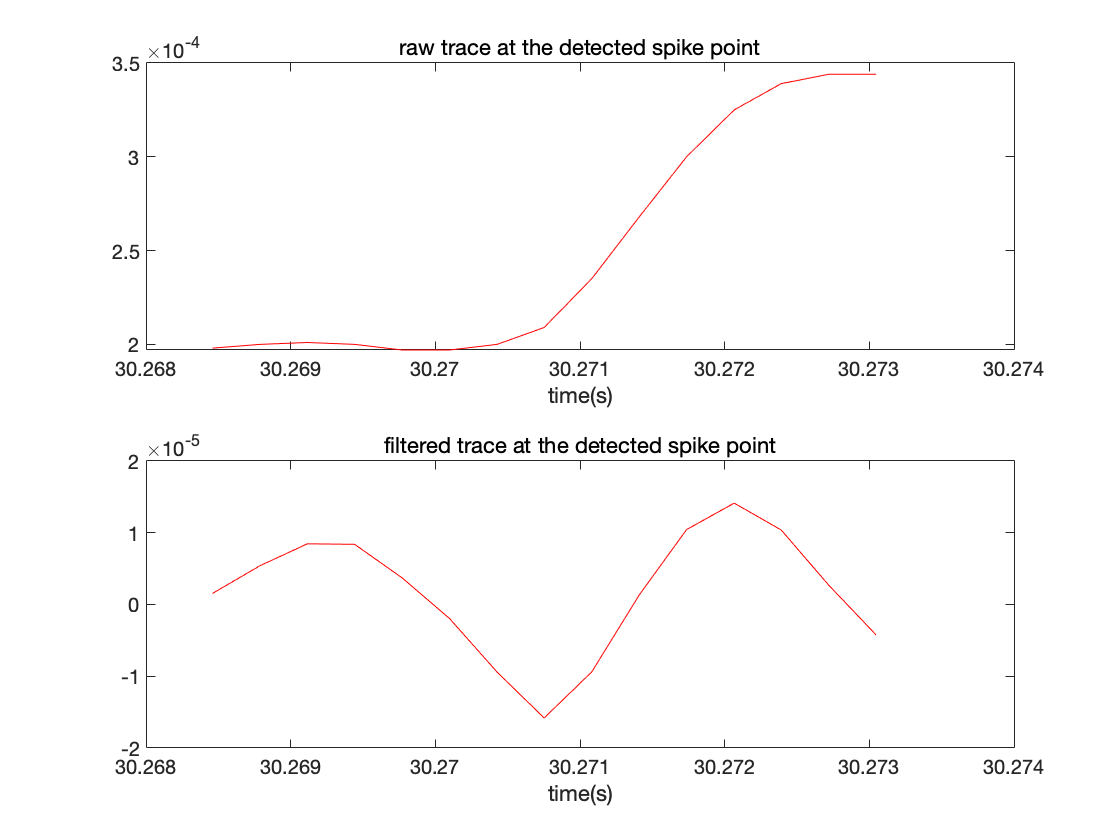

spikeTimestamps = o1_ch8_m1.spikeTimestamps;
ts = spikeTimestamps(1); %location of the 20th spike
tsInterval = ts + (-o1_ch8_m1.timestampsPrePeak : o1_ch8_m1.timestampsPostPeak);

figure
subplot(2,1,1)
pRaw = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.raw(tsInterval));
pRaw.Color = 'red';
title('raw trace at the detected spike point');
xlabel('time(s)');

subplot(2,1,2)
pFiltered = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.filtered(tsInterval));
pFiltered.Color = 'red';
title('filtered trace at the detected spike point');
xlabel('time(s)');

## Figure 2.h

PCA and average waveform for each cluster

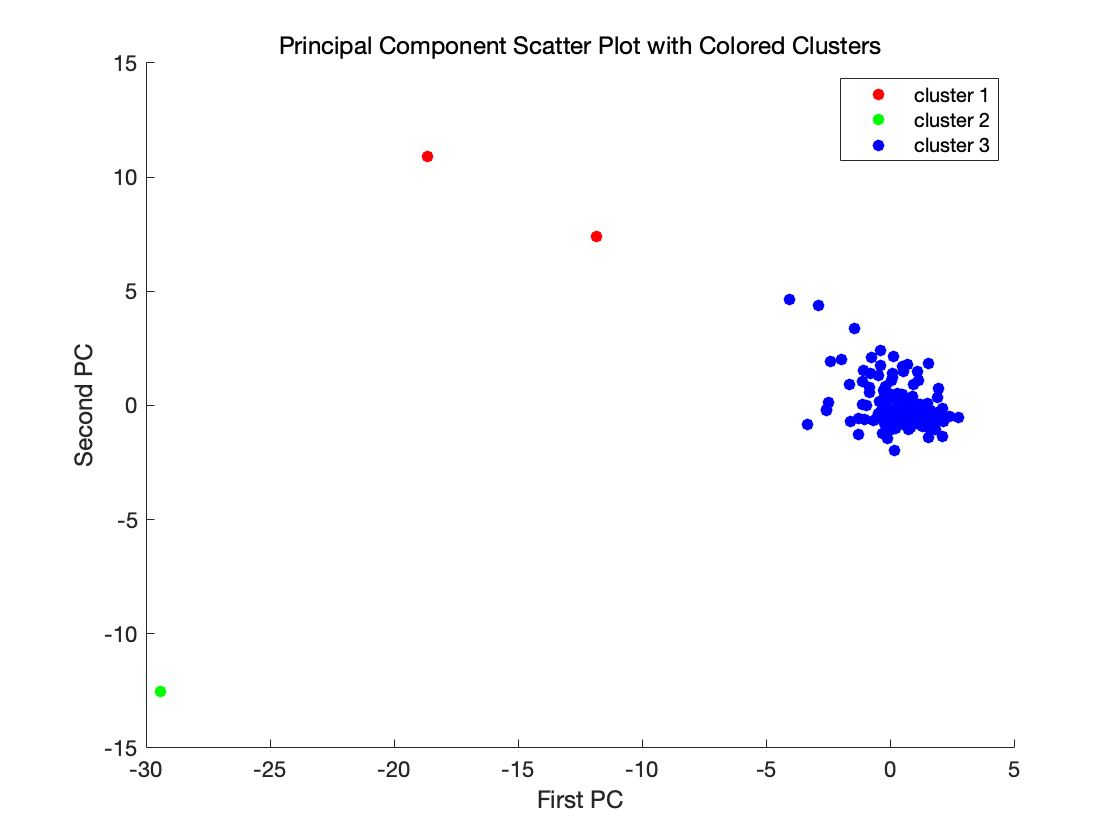

figure

o1_ch8_m1.drawPCA()

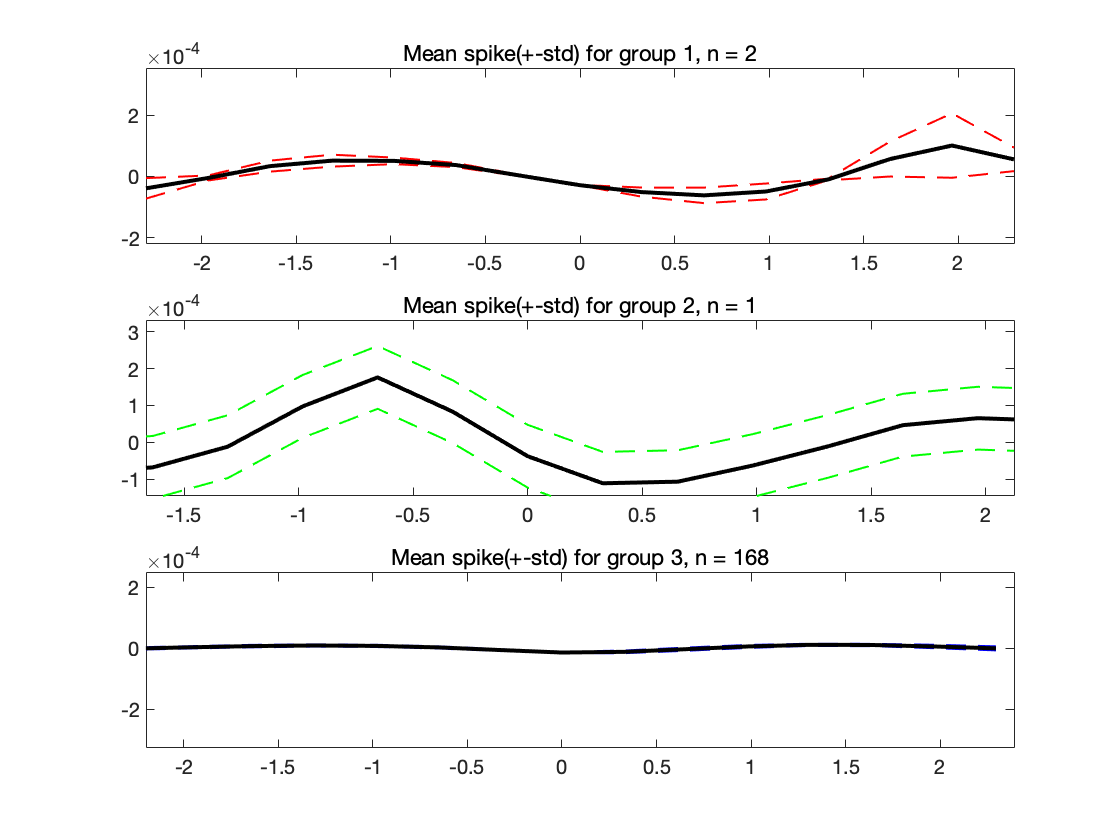

nSpikesNow = 2

nSpikesNow = 1

nSpikesNow = 168


figure
o1_ch8_m1.drawClusterMeanSpikes();

## Figure 2.i

colored raster plot. 클러스터 3개일 때는 파란색이 압도적으로 많아 구분이 잘 되지 않으므로, 일시적으로 클러스터 5개로 수정

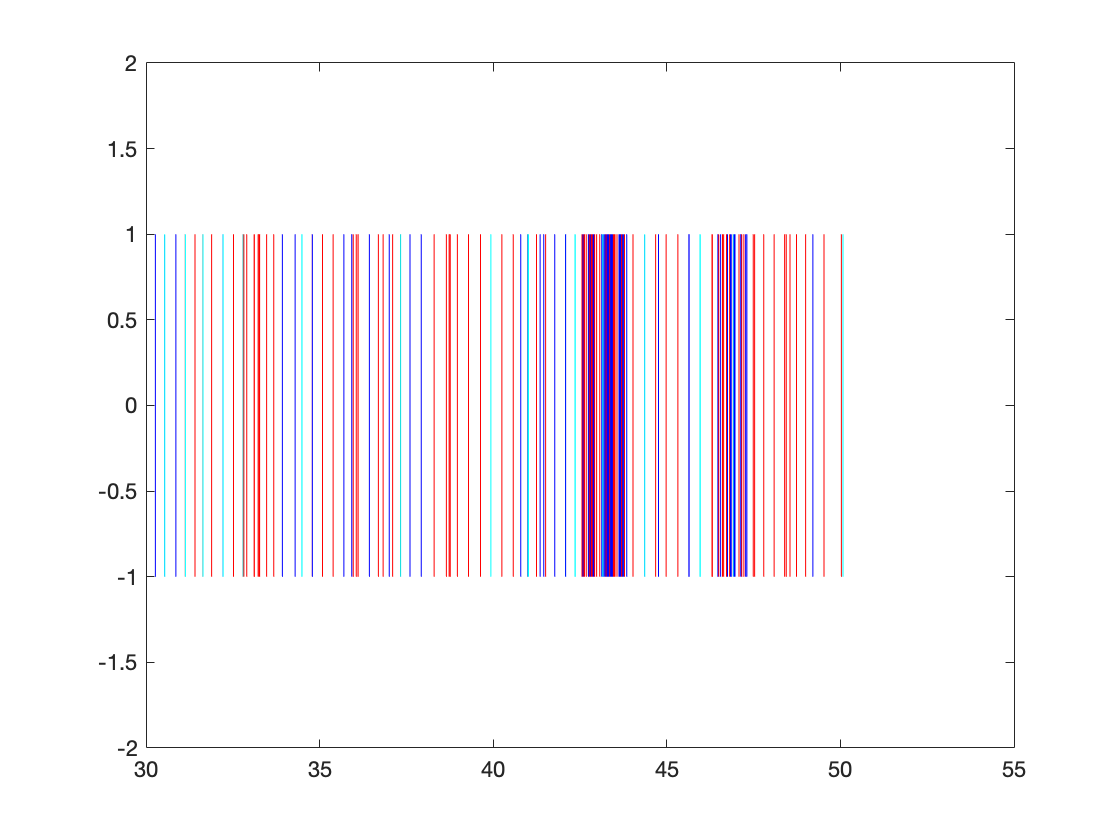

o1_ch8_m1.getKmeansClusters(5,1);
figure
o1_ch8_m1.drawColoredRaster();

o1_ch8_m1.getKmeansClusters(3,1);


## Figure 2.j.

interspike intervals histogram

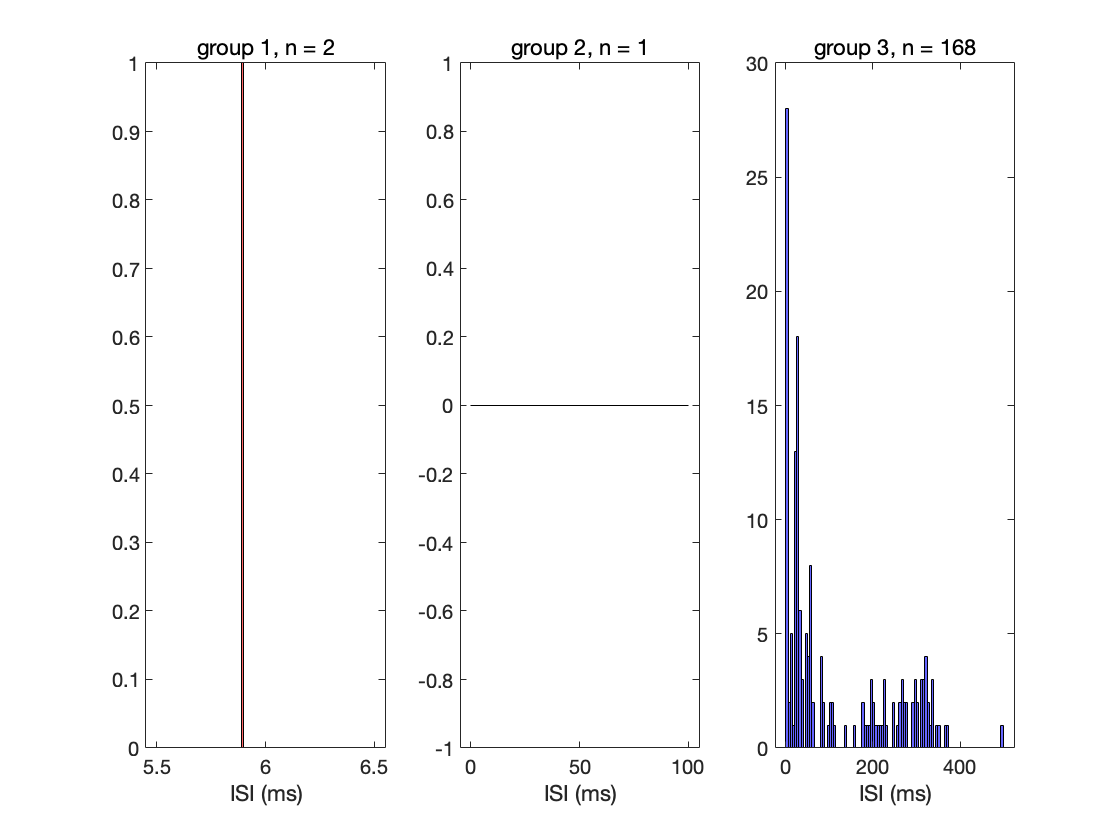

h =   Histogram - 속성 있음:

             Data: 5.8982
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0100
        BinLimits: [5.5000 6.5000]
    Normalization: 'count'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  모든 속성 표시


h =   Histogram - 속성 있음:

             Data: []
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 1
        BinLimits: [0 100]
    Normalization: 'count'
        FaceColor: [0 1 0]
        EdgeColor: [0 0 0]

  모든 속성 표시


h =   Histogram - 속성 있음:

             Data: [1×167 double]
           Values: [28 2 5 1 13 18 6 3 0 5 4 8 2 0 0 0 4 2 0 1 2 2 1 0 0 0 0 1 0 0 0 1 0 0 0 2 1 1 1 3 2 1 1 1 1 3 1 0 0 2 0 1 2 3 2 2 0 0 2 3 2 0 3 3 4 2 1 3 0 1 1 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 4.9900
        BinLimits: [0 499]
    Normalization: 'count'
        FaceColor: [0 0 1]
        EdgeColor: [0 0 0]

  모든 속성 표시


figure
o1_ch8_m1.drawISI();

## Figure 2.k

theta waves and theta phase

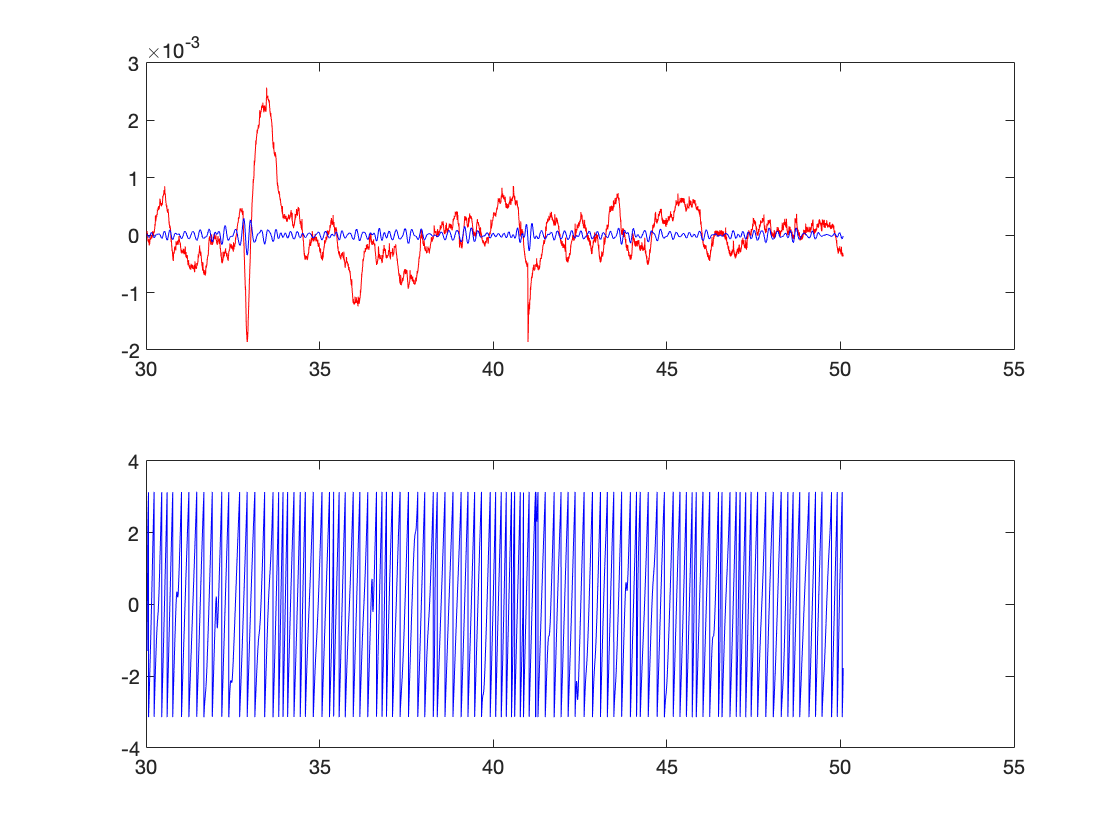

figure
subplot(2,1,1)
p_raw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
p_raw.Color = 'red';

hold on;

p_thetaWaves = plot(o1_ch8_m1.t, o1_ch8_m1.thetaWaves);
p_thetaWaves.Color = 'blue';

hold off;

subplot(2,1,2)
p_thetaPhases = plot(o1_ch8_m1.t, o1_ch8_m1.thetaPhases);
p_thetaPhases.Color = 'blue';

## Figure 4.b.

                             %organoid, channel, month     
o1_ch1_m1 = channel("rawData.csv", 1, 1, 1);
o1_ch2_m1 = channel("rawData.csv", 1, 2, 1);
o1_ch1_m2 = channel("rawData.csv", 1, 1, 2);
o1_ch2_m2 = channel("rawData.csv", 1, 2, 2);

100-3000hz로 필터링

o1_ch1_m1.bandPass([100,3000])

o1_ch2_m1.bandPass([100,3000])

o1_ch1_m2.bandPass([100,3000])

o1_ch2_m2.bandPass([100,3000])

cluster 개수 3개, spike waveform 길이 +- 2ms로 spike detection 실행

o1_ch1_m1.detectSpikes(3,2,2)
o1_ch2_m1.detectSpikes(3,2,2)
o1_ch1_m2.detectSpikes(3,2,2)
o1_ch2_m2.detectSpikes(3,2,2)

channel object별로 raw trace 그리기. ylim 옵션을 이용해 비교대상끼리 y축 스케일 통일.

figure
%month 1

%ch1
subplot(2,2,1)
p = plot(o1_ch1_m1.t, o1_ch1_m1.raw);
p.Color = 'red'

p =   Line - 속성 있음:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×61183 double]
              YData: [1×61183 double]
              ZData: [1×0 double]

  모든 속성 표시


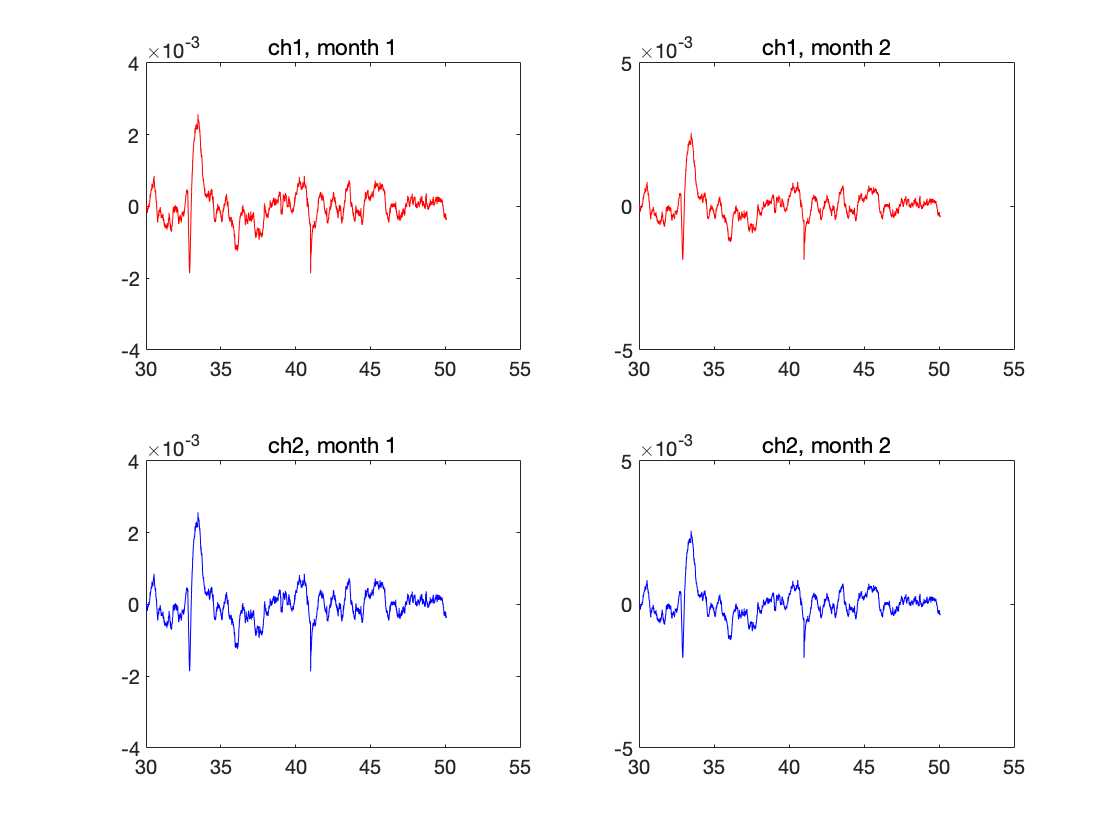

title('ch1, month 1')
ylim([-4,4]*1e-3);%ylim 조절

%ch2
subplot(2,2,3)
p_o1_ch2_m1 = o1_ch2_m1.drawRaw('blue');
title('ch2, month 1')
ylim([-4,4]*1e-3);%ylim 조절


%month 2
%ch1
subplot(2,2,2)
p_o1_ch1_m2 = o1_ch1_m2.drawRaw('red');
title('ch1, month 2')
ylim([-5,5]*1e-3);%ylim 조절

%ch2
subplot(2,2,4)
p_o1_ch2_m2 = o1_ch2_m2.drawRaw('blue');
title('ch2, month 2')
ylim([-5,5]*1e-3);%ylim 조절

channel object별로 mean spike 그리기.

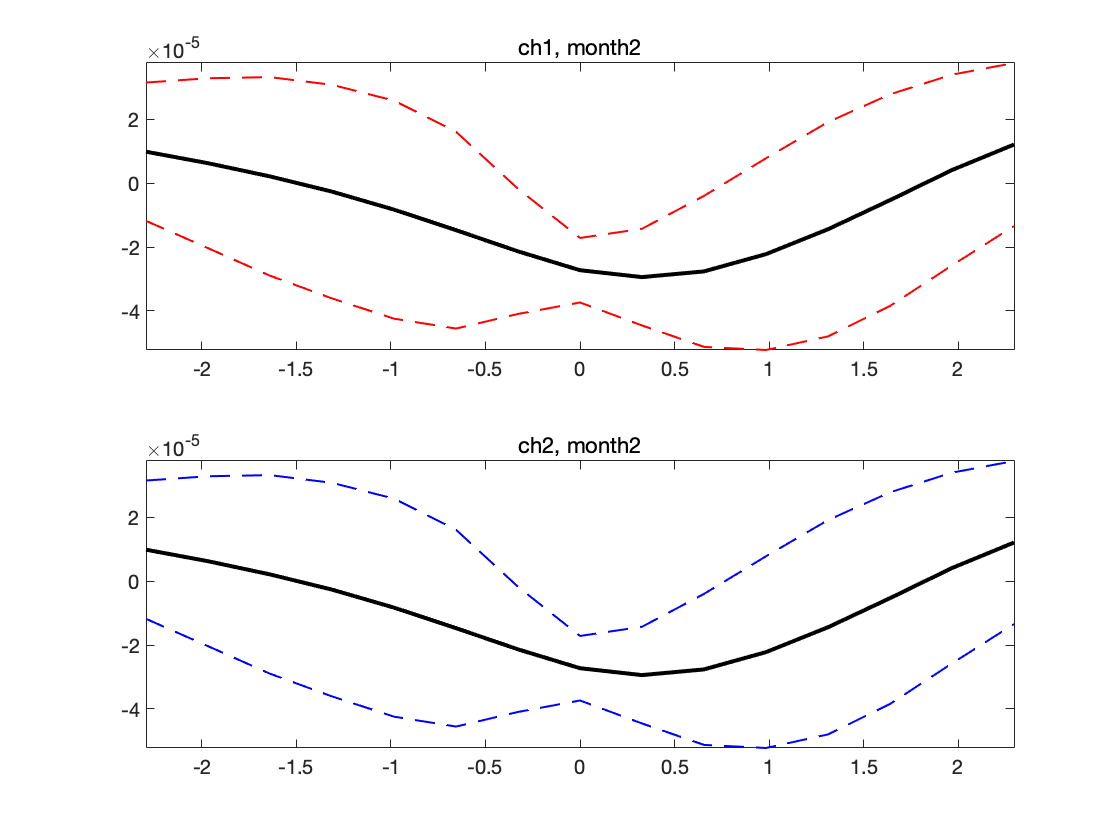

figure
subplot(2,1,1)
o1_ch1_m2.drawMeanSpike('red')
title('ch1, month2')
subplot(2,1,2)
o1_ch2_m2.drawMeanSpike('blue')
title('ch2, month2')

## Figure 4.c.

spectrogram(signal processing toolbox 필요)

x축 0s = 데이터 시작 시간(이 데이터에서는 약 30s)

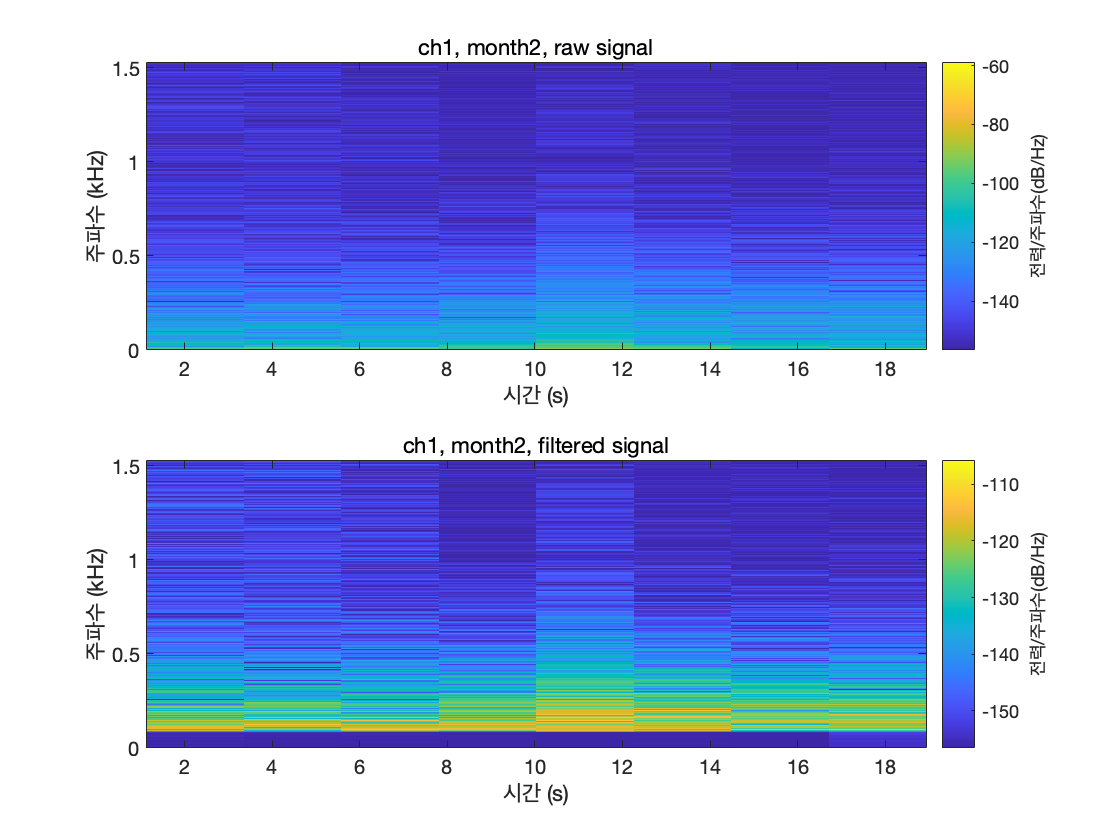

figure
subplot(2,1,1)
spectrogram(o1_ch1_m2.raw, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, raw signal')

subplot(2,1,2)
spectrogram(o1_ch1_m2.filtered, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, filtered signal')

## Figure 4.d

power spectrums(signal processing toolbox 필요)

논문에서는 여러 month의 raw data를 비교하지만, 이 예제에서는 데이터 파일이 하나밖에 없으므로 플롯에서 구분이 되도록 month2에서는 filtered data를 사용

figure

xTable = timetable(seconds(o1_ch1_m1.t), o1_ch1_m1.raw); %raw data
[pxx,f] = pspectrum(xTable);
month1 = plot(f,pow2db(pxx));
month1.Color = 'red'

month1 =   Line - 속성 있음:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×4096 double]
              YData: [1×4096 double]
              ZData: [1×0 double]

  모든 속성 표시



hold on

xTable = timetable(seconds(o1_ch1_m2.t), o1_ch1_m2.filtered); %filtered data
[pxx,f] = pspectrum(xTable);
month2 = plot(f,pow2db(pxx));
month2.Color = 'blue'

month2 =   Line - 속성 있음:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×4096 double]
              YData: [1×4096 double]
              ZData: [1×0 double]

  모든 속성 표시


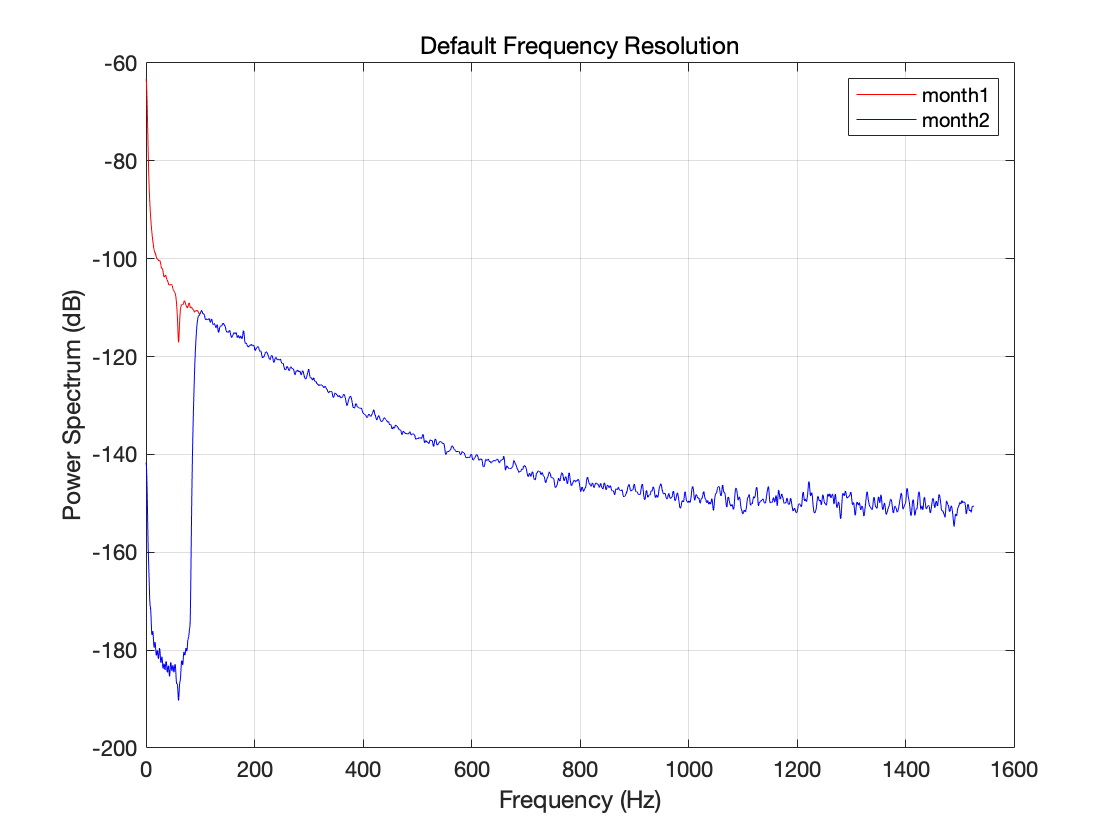


grid on

legend('month1', 'month2')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Default Frequency Resolution')

## Figure 4.f.

phase-space analysis

원 논문에서는 sampling frequency가 30000으로 높아서, spike +- 2ms가 121개의 timestamp로 구성되므로(앞으로 60, 뒤로 60) trajectory의 모양이 복잡함(121 steps)

본 예제에서는 sampling frequency가 약 3000으로 낮아서, spike +- 2ms가 15개의 timestamp로 구성되므로(앞으로 7, 뒤로 7. 반올림 때문) trajectory의 모양이 단순함(15 steps)

figure
o1_ch1_m1.drawPhaseSpace('red')

V = 	1.0e+-4 *

    0.3926    0.3566    0.3152    0.2676    0.2113    0.1470    0.0806    0.0216         0    0.0179    0.0719    0.1498    0.2409    0.3352


hold on
o1_ch1_m2.drawPhaseSpace('blue')

V = 	1.0e+-4 *

    0.3926    0.3566    0.3152    0.2676    0.2113    0.1470    0.0806    0.0216         0    0.0179    0.0719    0.1498    0.2409    0.3352


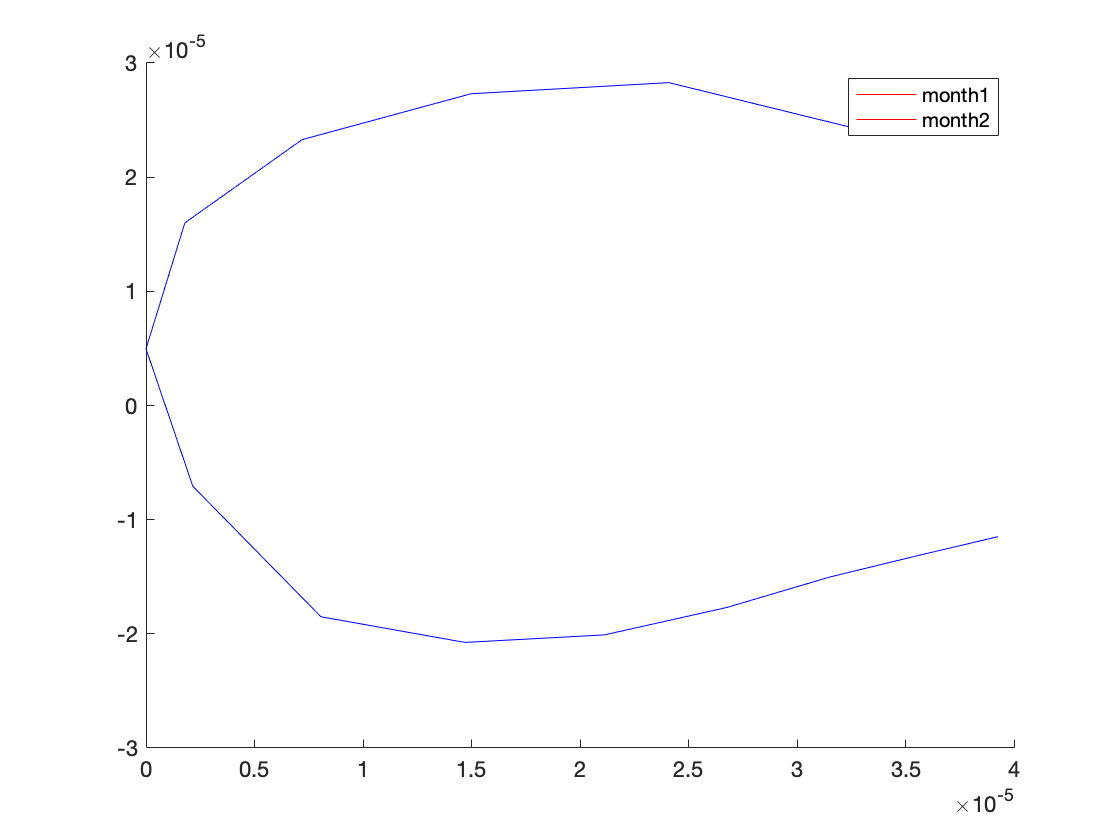

hold off
legend('month1', 'month2')

o1_ch1_m1

o1_ch1_m1 =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 1
                    month: 1
                       sf: 3.0518e+03
                  msPerTs: 0.3277
              nTimestamps: 61183
                startTime: 30.0312
                        t: [61183×1 double]
                      raw: [61183×1 double]
                 filtered: [61183×1 double]
        timestampsPrePeak: 7
       timestampsPostPeak: 7
          spikeTimestamps: [1×400 double]
    spikeTimestampsMatrix: []
           spikeWaveforms: [400×15 double]
                 PCScores: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
                      ISI: []
               thetaWaves: []
              thetaPhases: []
         spikeThetaAngles: []
            clusterColors: [6×1 string]


la = longtermAnalyzer()

la =   longtermAnalyzer - 속성 있음:

     channels: [1×1 struct]
    nChannels: 0


%organ, ch, month
ch111 = channel("ch6.csv", 1, 1, 1)

다음 사용 중 오류가 발생함: readmatrix (158번 라인)
'ch6.csv'을(를) 찾거나 열 수 없습니다. 경로와 파일 이름 또는 파일 권한을 확인하십시오.

오류 발생: channel (31번 라인)
            data = readmatrix(filename);

ch111.bandPass([300,3000]);
ch111.detectSpikes(5,2,2);

ch122 = channel("ch6.csv", 1, 2, 2)
ch122.bandPass([300,1000]);
ch122.detectSpikes(5,2,2);

ch211 = channel("ch6.csv", 2, 1, 1)
ch211.bandPass([300,1500]);
ch211.detectSpikes(5,2,2);

ch222 = channel("ch6.csv", 2, 2, 2)
ch222.bandPass([300,2000]);
ch222.detectSpikes(5,2,2);

ch311 = channel("ch6.csv", 3, 1, 2)
ch311.bandPass([300,1300]);
ch311.detectSpikes(5,2,2);

ch322 = channel("ch6.csv", 2, 1, 2)
ch322.bandPass([300,600]);
ch322.detectSpikes(5,2,2);

la.addChannel(ch111)
la.addChannel(ch122)
la.addChannel(ch211)
la.addChannel(ch222)
la.addChannel(ch311)
la.addChannel(ch322)

la.drawPhaseSpace(1,1)